clear all;
clc;


User Inputs

%fn = "res_per_cap_buffer3.csv";
%startFreq = 264e3;

%fn = "res_per_cap_buffer_ncycle_1_trial1.csv";
%fn = "res_per_cap_buffer_ncycle_1_trial2.csv";
%fn = "res_per_cap_buffer_ncycle_2_trial1.csv";
%fn = "res_per_cap_buffer_healthy_50us_on_100cycles.csv";
%fn = "res_per_cap_buffer_healthy_100us_on_100cycles.csv";

%fn = "res_per_cap_buffer_fres237kHz_on100us_n50_bad.csv";
%fn = "res_per_cap_buffer_fres237kHz_on100us_n50_bad3.csv";
%fn = "res_per_cap_buffer_fres237kHz_on200us_n100_good2.csv";    %10 % pos, 25 % neg


%fn = "res_per_cap_buffer_fres237kHz_on200us_n100_25negp_35posp_100ocd_toroid.csv";
%%fn = "res_per_cap_buffer_fres264kHz_on200us_n100_35negp_5posp_300ocd_toroid_wire_breakout_racing_sparks.csv"; % legacy
%fn = "res_per_cap_buffer_fres237kHz_on200us_n100_25negp_35posp_200ocd_toroid2.csv";  

fn = "1-4_run_trial1.csv"

fn = "1-4_run_trial1.csv"



% Min/Max tracked frequencies (%)
max_posDeviation_per = 5;   
max_negDeviation_per = 35;

% Tick frequency of HRTIM timers (Hz)
hrtim_tick_freq_hz = 170e6;

% Start (open-loop) frequency (Hz)
startFreq = 264e3;

% PRF on time (sec)
prf_ontime = 50e-6;


Derived Params

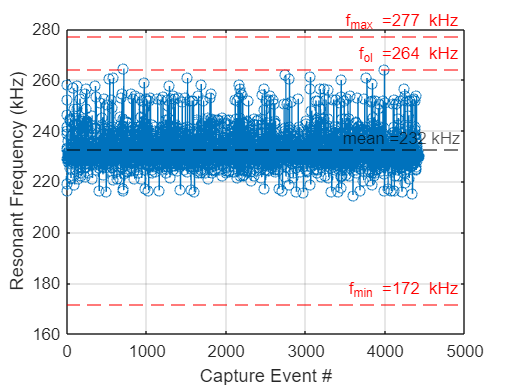

n_cycles = floor(prf_ontime / (1/startFreq));

% Read the CSV file into a numeric matrix
%csv = readmatrix(fn);
csv = nonzeros(readmatrix(fn)); % strip out the zeros

% Convert TIME Capture 1 into resosnant frequency (Hz)
res_freq = hrtim_tick_freq_hz./csv;
res_freq_mean = mean(res_freq);
res_freq_std = std(res_freq);

maxTrackedFreq =  startFreq * (max_posDeviation_per/100 + 1);
minTrackedFreq =  startFreq * (1 - max_negDeviation_per/100 );

prf_cycle_bounds = 0:n_cycles:length(res_freq);

figure()
plot(res_freq/1e3,'-o');
hold on;
yline(maxTrackedFreq/1e3, '--r', sprintf("f_{max} =%0.0f kHz",maxTrackedFreq/1e3));
hold on;
yline(minTrackedFreq/1e3, '--r',  sprintf("f_{min} =%0.0f kHz",minTrackedFreq/1e3));
hold on;
yline(startFreq/1e3, '--r', sprintf("f_{ol} =%0.0f kHz",startFreq/1e3));
hold on;
yline(res_freq_mean/1e3, '--k', sprintf("mean =%0.0f kHz",res_freq_mean/1e3));

%xline(prf_cycle_bounds,'--')
xlabel('Capture Event #');
ylabel('Resonant Frequency (kHz)');
grid on;


fprintf("Resonant Frequency Mean: %0.1f kHz",res_freq_mean/1e3);

Resonant Frequency Mean: 232.4 kHz

fprintf("Resonant Frequency Standard Deviation: %0.2f kHz",res_freq_std/1e3);

Resonant Frequency Standard Deviation: 5.48 kHz

fprintf("3sigma: %0.2f kHz",3*res_freq_std/1e3);

3sigma: 16.44 kHz


on_time_sec = 200e-6;
n_cycles = 100;
n_cap = compute_num_cap_events(startFreq, on_time_sec, n_cycles);

% Computes the size of the buffer on firmware side that
% would be necessary to store all capture events
% Each capture is a uint32_t (4 bytes)
n_bytes = n_cap*4; 

fprintf("Number of capture events: %d",n_cap);

Number of capture events: 5200

fprintf("Number of bytes to store all capture events: %d bytes",n_bytes);

Number of bytes to store all capture events: 20800 bytes

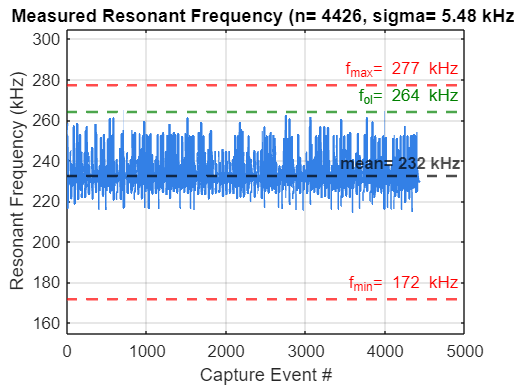


% Plot capture buffer
fn = "1-4_run_trial1.csv";
[f_res_mean1,f_res_std1,f_res_spe1] = res_per_cap_buffer_plot(fn,264e3,[35 5]);

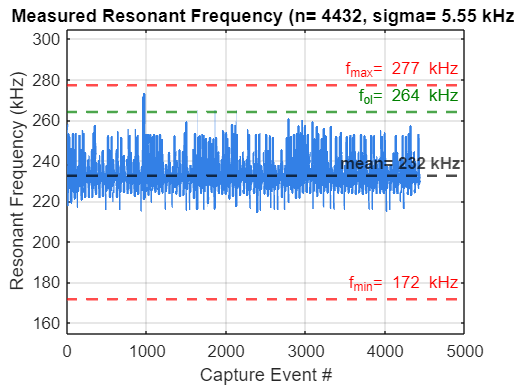


% Plot capture buffer
fn = "1-4_run_trial2.csv";
[f_res_mean2,f_res_std2,f_res_spe2] = res_per_cap_buffer_plot(fn,264e3,[35 5]);